# Group comparison demonstration

This analysis script provides a demonstration of how you can compare two different groups. The approach for group comparisons is very simple. 

- Run a model to do parameter estimation for group 1. 

- Run a model to do parameter estimation for group 2.

- Then compare group-level parameters.

*THIS IS NOT A REPEATED MEASURES COMPARISON. We are just comparing group level parameter estimates*.

% define a cell array of the variables you want to compare
variables_of_interest = {'logk'};

Run setup routine

toolbox_path = fullfile(pwd,'..','ddToolbox');
addpath(toolbox_path)
ddAnalysisSetUp();

Temporarily adding toolbox subdirecties to the path: 
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/CODA
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/Data
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/DeterministicFunction
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/Variables
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/dependencies
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/dependencies/latex_fig
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/hypothesis-testing
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/models
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/models/nonparametric_models
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/models/parametric_models
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/models/pa

plotting defaults set





You are now up and running with:
Hierarchical Bayesian estimation and hypothesis testing for delay discounting tasks

More information available in the paper at: doi:10.3758/s13428-015-0672-2
Help can be found at: https://github.com/drbenvincent/delay-discounting-analysis/wiki




Define common properties for the parameter estimation

mcmcparams = struct('nsamples', 5000, 'nchains', 4, 'nburnin', 1000);
pointEstimateType = 'median';
sampler = 'jags';
shouldPlot = 'no';

Define paths to the datasets

datapath1 = fullfile(pwd,'datasets','group_comparison','group1');
datapath2 = fullfile(pwd,'datasets','group_comparison','group2');

group1files = allFilesInFolder(datapath1, 'txt');

group1files =     'AB-C-2016Feb12-10.47.txt'
    'AD-C-2016Feb26-14.32.txt'
    'AH-C-2016Feb23-14.09.txt'
    'AT-C-2016Feb26-12.26.txt'
    'BD-C-2016Feb09-17.28.txt'
    'DG-C-2016Feb25-17.04.txt'
    'JDA-C-2016Feb09-16.34.txt'
    'JSL-C-2016Feb25-12.25.txt'
    'RR-C-2016Feb23-13.35.txt'
    'SE-C-2016Feb24-15.21.txt'


group2files = allFilesInFolder(datapath2, 'txt');

group2files =     'AB-F-2016Feb29-09.45.txt'
    'AD-F-2016Feb12-11.19.txt'
    'AH-F-2016Feb10-10.19.txt'
    'AT-F-2016Feb12-09.21.txt'
    'BD-F-2016Feb23-11.09.txt'
    'DG-F-2016Feb11-11.46.txt'
    'JDA-F-2016Feb24-09.20.txt'
    'JSL-F-2016Feb11-10.47.txt'
    'RR-F-2016Feb12-10.10.txt'
    'SE-F-2016Feb10-09.24.txt'


# Conduct parameter estimation on the datasets

group1 = ModelHierarchicalLogK(...
	Data(datapath1, 'files', group1files),...
	'savePath', fullfile(pwd,'output','group1'),...
	'pointEstimateType', pointEstimateType,...
	'sampler', sampler,...
	'shouldPlot', shouldPlot,...
	'shouldExportPlots', false,...
	'mcmcParams', mcmcparams);

You have created a Data object


ans =    1


A copy of the group-level dataset just constructed has been saved as a text file:
/Users/btvincent/git-local/delay-discounting-analysis/demo/datasets/group_comparison/group1/groupLevelData/COMBINED_DATA.txt


The following data files were imported:


  Columns 1 through 5

    'AB-C-2016Feb12-10…'    'AD-C-2016Feb26-14…'    'AH-C-2016Feb23-14…'    'AT-C-2016Feb26-12…'    'BD-C-2016Feb09-17…'

  Columns 6 through 10

    'DG-C-2016Feb25-17…'    'JDA-C-2016Feb09-1…'    'JSL-C-2016Feb25-1…'    'RR-C-2016Feb23-13…'    'SE-C-2016Feb24-15…'




Running JAGS (4 chains, 1250 samples each)
Running chain 3 (parallel execution)
Running chain 4 (parallel execution)
Running chain 1 (parallel execution)
Running chain 2 (parallel execution)
Calculating statistics


Calculating posterior predictive measures...


ans =    1



Rhat for: logk	AB-C-2016Feb12-10.47:	0.99989	
AD-C-2016Feb26-14.32:	0.99991	
AH-C-2016Feb23-14.09:	0.99967	
AT-C-2016Feb26-12.26:	0.99993	
BD-C-2016Feb09-17.28:	0.99985	
DG-C-2016Feb25-17.04:	1.00080	
JDA-C-2016Feb09-16.34:	1.00193	
JSL-C-2016Feb25-12.25:	1.00094	
RR-C-2016Feb23-13.35:	1.00124	
SE-C-2016Feb24-15.21:	1.00010	
GROUP:	0.99990	

Rhat for: alpha	AB-C-2016Feb12-10.47:	1.00179	
AD-C-2016Feb26-14.32:	1.00119	
AH-C-2016Feb23-14.09:	1.00221	
AT-C-2016Feb26-12.26:	1.00286	
BD-C-2016Feb09-17.28:	1.00319	
DG-C-2016Feb25-17.04:	1.00243	
JDA-C-2016Feb09-16.34:	1.00066	
JSL-C-2016Feb25-12.25:	1.00476	
RR-C-2016Feb23-13.35:	1.00081	
SE-C-2016Feb24-15.21:	1.00125	
GROUP:	1.00221	

Rhat for: epsilon	AB-C-2016Feb12-10.47:	1.00011	
AD-C-2016Feb26-14.32:	1.00034	
AH-C-2016Feb23-14.09:	1.00107	
AT-C-2016Feb26-12.26:	1.00766	
BD-C-2016Feb09-17.28:	0.99972	
DG-C-2016Feb25-17.04:	0.99973	
JDA-C-2016Feb09-16.34:	1.00026	
JSL-C-2016Feb25-12.25:	1.00171	
RR-C-2016Feb23-13.35:	1.00013	
SE-C-2016Fe

finalTable =                              logk_mean    alpha_mean    epsilon_mean     Var1      Var2      Var3
                             _________    __________    ____________    ______    _______    ____

    AB-C-2016Feb12-10.47     -8.7376      2.4083        0.051992        14.648    0.86111      0 
    AD-C-2016Feb26-14.32     -5.5124      2.2147        0.057042        10.638    0.77778      0 
    AH-C-2016Feb23-14.09      -3.649      2.4442        0.079762        8.0623       0.75      0 
    AT-C-2016Feb26-12.26     -5.4179      3.1795        0.092461        8.6884       0.75      0 
    BD-C-2016Feb09-17.28     -4.5568      2.2837         0.05727        11.485    0.80488      0 
    

ans =    1


Table was exported to:
	/Users/btvincent/git-local/delay-discounting-analysis/demo/output/group1/parameterEstimates_Posterior_median.csv


Methods for class ModelHierarchicalLogK:

ModelHierarchicalLogK                   exportParameterEstimates                plot                                    
conditionalDiscountRates                getGroupLevelSamples                    plotMCMCchains                          
conditionalDiscountRates_GroupLevel     get_inferred_present_subjective_values  postSamplingActivities                  
conductInference                        get_nChains                             
experimentPlot                          initialiseChainValues                   



group2 = ModelHierarchicalLogK(...
	Data(datapath2, 'files', group2files),...
	'savePath', fullfile(pwd,'output','group2'),...
	'pointEstimateType', pointEstimateType,...
	'sampler', sampler,...
	'shouldPlot', shouldPlot,...
	'shouldExportPlots', false,...
	'mcmcParams', mcmcparams);

You have created a Data object


ans =    1


A copy of the group-level dataset just constructed has been saved as a text file:
/Users/btvincent/git-local/delay-discounting-analysis/demo/datasets/group_comparison/group2/groupLevelData/COMBINED_DATA.txt


The following data files were imported:


    'AB-F-2016Feb29-09.45.txt'
    'AD-F-2016Feb12-11.19.txt'
    'AH-F-2016Feb10-10.19.txt'
    'AT-F-2016Feb12-09.21.txt'
    'BD-F-2016Feb23-11.09.txt'
    'DG-F-2016Feb11-11.46.txt'
    'JDA-F-2016Feb24-09.20.txt'
    'JSL-F-2016Feb11-10.47.txt'
    'RR-F-2016Feb12-10.10.txt'
    'SE-F-2016Feb10-09.24.txt'




Running JAGS (4 chains, 1250 samples each)
Running chain 2 (parallel execution)
Running chain 1 (parallel execution)
Running chain 4 (parallel execution)
Running chain 3 (parallel execution)
Calculating statistics


Calculating posterior predictive measures...


ans =    1



Rhat for: logk	AB-F-2016Feb29-09.45:	1.00021	
AD-F-2016Feb12-11.19:	1.00078	
AH-F-2016Feb10-10.19:	1.00051	
AT-F-2016Feb12-09.21:	1.00379	
BD-F-2016Feb23-11.09:	1.00056	
DG-F-2016Feb11-11.46:	1.00030	
JDA-F-2016Feb24-09.20:	1.00324	
JSL-F-2016Feb11-10.47:	0.99981	
RR-F-2016Feb12-10.10:	0.99998	
SE-F-2016Feb10-09.24:	0.99980	
GROUP:	1.00038	

Rhat for: alpha	AB-F-2016Feb29-09.45:	1.00284	
AD-F-2016Feb12-11.19:	1.00355	
AH-F-2016Feb10-10.19:	1.00199	
AT-F-2016Feb12-09.21:	1.00685	
BD-F-2016Feb23-11.09:	1.00213	
DG-F-2016Feb11-11.46:	1.00293	
JDA-F-2016Feb24-09.20:	1.01085	(WARNING: poor convergence)
JSL-F-2016Feb11-10.47:	1.00356	
RR-F-2016Feb12-10.10:	1.00646	
SE-F-2016Feb10-09.24:	1.00084	
GROUP:	1.00152	

Rhat for: epsilon	AB-F-2016Feb29-09.45:	1.00101	
AD-F-2016Feb12-11.19:	1.00130	
AH-F-2016Feb10-10.19:	1.00081	
AT-F-2016Feb12-09.21:	1.00001	
BD-F-2016Feb23-11.09:	1.00095	
DG-F-2016Feb11-11.46:	1.00254	
JDA-F-2016Feb24-09.20:	1.00972	
JSL-F-2016Feb11-10.47:	1.00011	
RR-F-2016Feb12-

finalTable =                              logk_mean    alpha_mean    epsilon_mean     Var1      Var2      Var3
                             _________    __________    ____________    ______    _______    ____

    AB-F-2016Feb29-09.45     -8.6321       2.515        0.069068        14.513    0.88889      0 
    AD-F-2016Feb12-11.19     -2.9345      3.0807        0.086556        9.3804    0.80556      0 
    AH-F-2016Feb10-10.19     -5.8794      2.0978         0.04387        14.274    0.86111      0 
    AT-F-2016Feb12-09.21     -1.8426      2.9745        0.092069        6.1651    0.72222      0 
    BD-F-2016Feb23-11.09     -2.7314      2.0809        0.061653        10.251    0.80556      0 
    

ans =    1


Table was exported to:
	/Users/btvincent/git-local/delay-discounting-analysis/demo/output/group2/parameterEstimates_Posterior_median.csv


Methods for class ModelHierarchicalLogK:

ModelHierarchicalLogK                   exportParameterEstimates                plot                                    
conditionalDiscountRates                getGroupLevelSamples                    plotMCMCchains                          
conditionalDiscountRates_GroupLevel     get_inferred_present_subjective_values  postSamplingActivities                  
conductInference                        get_nChains                             
experimentPlot                          initialiseChainValues                   



# Do the comparison

**NOTE: this works but is under development, so the exact way we invoke model comparison is likely to change in the future**

You will typically want to pick one method and stick with that. Below is a demonstration of each approach.

## METHOD 1: Parameter Estimation approach

Now you can make decisions about whether there are group level differences based upon whether the 95% credible region overlaps with zero (ie no group difference) or not.

ans =   UnivariateDistribution with properties:

      mean: -0.4601
    median: -0.4690
      mode: -0.9116


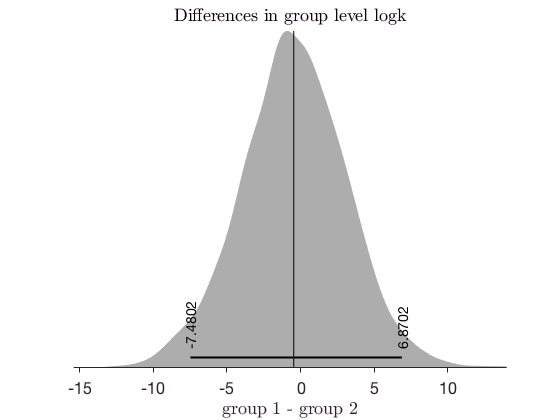

group1_minus_group2 = group_comparison(...
	group1,...
	group2,...
	variables_of_interest,...
	pointEstimateType,...
	'parameter estimation');

## METHOD 2: Hypothesis testing approach

TODO: Description here

group1_minus_group2 = group_comparison(...
	group1,...
	group2,...
	variables_of_interest,...
	pointEstimateType,...
	'bayesian hypothesis test');

## METHOD 3: Estimation with point estimates

TODO: Description here

group1_minus_group2 = group_comparison(...
	group1,...
	group2,...
	variables_of_interest,...
	pointEstimateType,...
	'point estimates');